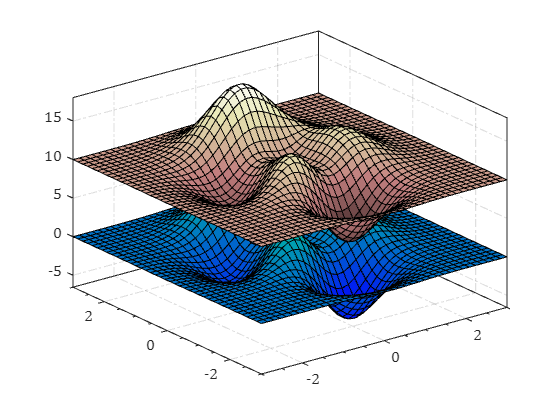

close all
defualtAxes()
[X,Y,Z]=peaks(40);
hold on;axis tight;grid on;view(3)
surfHdl1=surf(X,Y,Z);
surfHdl2=surf(X,Y,Z+10);

CM1=winter;
CM2=pink;
ZList1=linspace(min(min(surfHdl1.ZData)),max(max(surfHdl1.ZData)),size(CM1,1));
ZList2=linspace(min(min(surfHdl2.ZData)),max(max(surfHdl2.ZData)),size(CM2,1));
CMap1=cat(3,interp1(ZList1,CM1(:,1),surfHdl1.ZData),interp1(ZList1,CM1(:,2),surfHdl1.ZData),interp1(ZList1,CM1(:,3),surfHdl1.ZData));
CMap2=cat(3,interp1(ZList2,CM2(:,1),surfHdl2.ZData),interp1(ZList2,CM2(:,2),surfHdl2.ZData),interp1(ZList2,CM2(:,3),surfHdl2.ZData));
surfHdl1.CData=CMap1;
surfHdl2.CData=CMap2;